# Robotlar için Matematik Temelleri (RMT) – Proje 2/4

240201124 Ahmet Yiğit Bozkurt

clear; close all; clc;


PARAMETRELER (URDF'den alınacak değerler)


%% ROBOT AYARLARI (URDF verileri)
r_teker = 0.1;      % Tekerlek yarıçapı boyutu [m]
L_govde = 0.46;     % İki tekerlek arasındaki mesafe [m]


BÖLÜM A: SEMBOLİK KİNEMATİK (İLERİ & TERS)

% Diferansiyel sürüş modeli denklemleri:
% v = r_teker*(wd_sag + wd_sol)/2
% omega = r_teker*(wd_sag - wd_sol)/L_govde
% v ve omega biliniyorken tekerlek hızlarını (wd_sag, wd_sol) çöz.

syms V_sem W_sem r_sem L_sem real
syms wd_sag wd_sol real

denklem1 = V_sem == r_sem*(wd_sag + wd_sol)/2;
denklem2 = W_sem == r_sem*(wd_sag - wd_sol)/L_sem;

cozum = solve([denklem1, denklem2],[wd_sag, wd_sol],'ReturnConditions',true);
wd_sag_ifadesi = simplify(cozum.wd_sag);
wd_sol_ifadesi = simplify(cozum.wd_sol);

% Hesaplama için matlab fonksiyonuna dönüştürme
ters_kinematik = matlabFunction([wd_sag_ifadesi; wd_sol_ifadesi],'Vars',{V_sem,W_sem,r_sem,L_sem});

% İleri kinematik fonksiyonu (tekerlek hızlarından gövde hızına)
ileri_kinematik = @(hizR,hizL,r,L) deal( r*(hizR+hizL)/2, r*(hizR-hizL)/L );


BÖLÜM B: HIZ PROFİLİ OLUŞTURMA ve KİNEMATİK (Odometri)

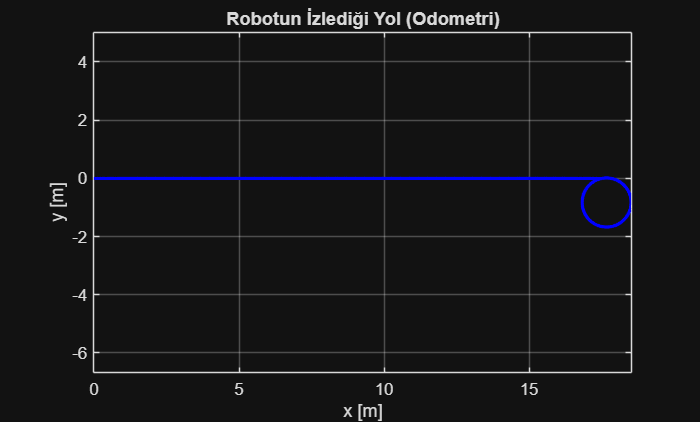

Sim_Suresi = 120; adim = 0.02;
zaman = 0:adim:Sim_Suresi;

% Hareket planı verileri
% [baslangic_t, bitis_t, w_sag_max (rad/s), w_sol_max (rad/s), rampa_suresi (s)]
hareket_plani = [ 0, 40,   5, 5, 5;     % düz gidiş (40 sn)
                  40, 80,  6, -6, 5;    % nokta dönüşü (40 sn)
                  80,120,  7, 4, 5 ];   % yay çizme (40 sn)

w_sag_ref = zeros(size(zaman)); 
w_sol_ref = zeros(size(zaman));

for k = 1:size(hareket_plani,1)
    t_basla = hareket_plani(k,1); t_bitis = hareket_plani(k,2);
    max_hiz_R = hareket_plani(k,3); max_hiz_L = hareket_plani(k,4);
    t_rampa = hareket_plani(k,5);

    % rampa_olustur fonksiyonu en sonda tanımlıdır
    w_sag_ref = w_sag_ref + rampa_olustur(zaman, t_basla, t_bitis, max_hiz_R, t_rampa);
    w_sol_ref = w_sol_ref + rampa_olustur(zaman, t_basla, t_bitis, max_hiz_L, t_rampa);
end

%% İleri kinematik hesabı: tekerlek devri -> v, omega
v_ref = zeros(size(zaman));
omega_ref = zeros(size(zaman));
for i=1:length(zaman)
    [v_ref(i), omega_ref(i)] = ileri_kinematik(w_sag_ref(i), w_sol_ref(i), r_teker, L_govde);
end

%% Konum Hesabı (Euler Yöntemi)
pos_x = zeros(size(zaman)); pos_y = zeros(size(zaman)); theta = zeros(size(zaman));
for i=2:length(zaman)
    dt_i = zaman(i) - zaman(i-1);
    pos_x(i) = pos_x(i-1) + v_ref(i-1)*cos(theta(i-1))*dt_i;
    pos_y(i) = pos_y(i-1) + v_ref(i-1)*sin(theta(i-1))*dt_i;
    theta(i) = theta(i-1) + omega_ref(i-1)*dt_i;
end

% Grafikler
figure('Name','Yörünge Analizi'); plot(pos_x,pos_y,'b-','LineWidth',2); axis equal; grid on;
xlabel('x [m]'); ylabel('y [m]'); title('Robotun İzlediği Yol (Odometri)');

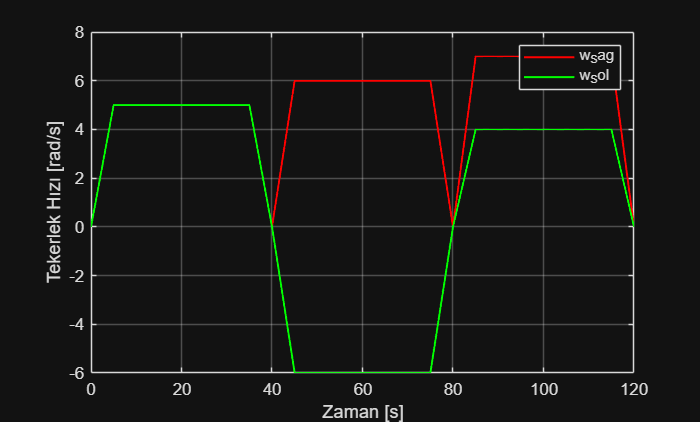


figure('Name','Motor Hızları'); plot(zaman,w_sag_ref,'r',zaman,w_sol_ref,'g','LineWidth',1.2);
xlabel('Zaman [s]'); ylabel('Tekerlek Hızı [rad/s]'); legend('w_Sag','w_Sol'); grid on;

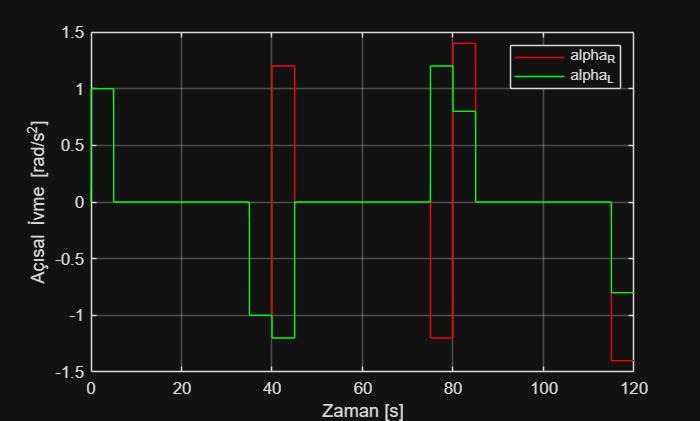


figure('Name','Motor İvmeleri'); acc_R = [0 diff(w_sag_ref)./diff(zaman)]; acc_L = [0 diff(w_sol_ref)./diff(zaman)];
plot(zaman,acc_R,'r',zaman,acc_L,'g'); xlabel('Zaman [s]'); ylabel('Açısal İvme [rad/s^2]'); legend('alpha_R','alpha_L'); grid on;

BÖLÜM C: KLOTOID TAKİBİ (Clothoid / Euler spiral)

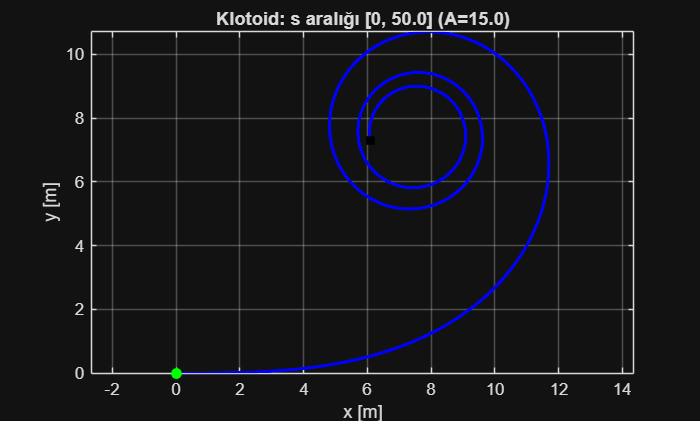

close all;

%% PARAMETRELER
yol_uzunlugu = 50;      
olcek = 15;             % ölçeklendirme faktörü
sabit_hiz = 0.6;        % robotun çizgisel hızı [m/s]
genislik = L_govde;     % tekerlek açıklığı [m]

% Yay uzunluğu ayrıştırma
N_nokta = 12000;          % yüksek çözünürlük
s_param = linspace(0, yol_uzunlugu, N_nokta);
ds = s_param(2)-s_param(1);

% Normalize edilmiş parametre
l_norm = s_param / olcek;

%% Fresnel integralleri
Fres_C = fresnelc(l_norm);
Fres_S = fresnels(l_norm);

%% Koordinatları Hesapla
koor_x = olcek * Fres_C;
koor_y = olcek * Fres_S;

%% Yönelim Açısını Hesapla
yonelem_acisi = atan2(diff(koor_y), diff(koor_x));
yonelem_acisi(end+1) = yonelem_acisi(end);  % son elemanı doldur

%% Eğrilik Hesabı (Euler eğriliği: k = s/A^2)
egrilik_k = s_param / (olcek^2);

%% Robot Açısal Hızı
w_robot = sabit_hiz * egrilik_k;  

%% Tekerlek Açısal Hızları
w_sag_teker = (sabit_hiz + (genislik/2)*w_robot) / r_teker;
w_sol_teker = (sabit_hiz - (genislik/2)*w_robot) / r_teker;

%% Klotoid Yolunu Çizdir
figure;
plot(koor_x, koor_y, 'b', 'LineWidth', 2); hold on;
plot(koor_x(1), koor_y(1), 'go','MarkerFaceColor','g');
plot(koor_x(end), koor_y(end), 'ks','MarkerFaceColor','k');

grid on;
title(sprintf('Klotoid: s aralığı [0, %.1f] (A=%.1f)', yol_uzunlugu, olcek));
xlabel('x [m]');
ylabel('y [m]');
axis equal;

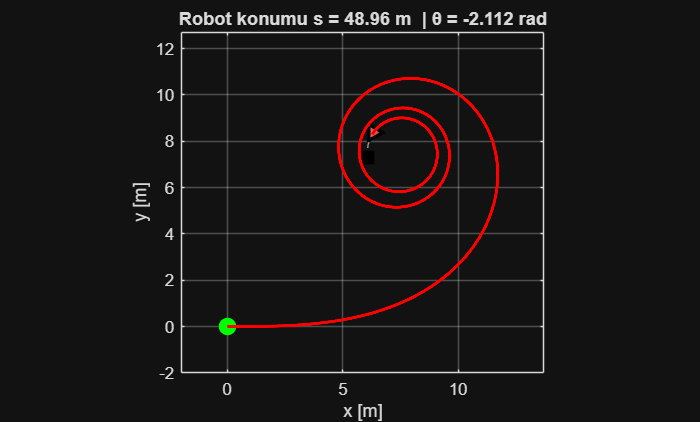


x_min=min(koor_x); x_max=max(koor_x);
y_min=min(koor_y); y_max=max(koor_y);
kenar_bosluk=2;

%% Animasyon Gösterimi
figure('Name','Animasyon','NumberTitle','off'); clf;
plot(koor_x, koor_y, '--','Color',[0.6 0.6 0.6]); hold on;

% Başlangıç ve bitiş işaretleri
plot(koor_x(1), koor_y(1),'go','MarkerSize',10,'MarkerFaceColor','g');
plot(koor_x(end), koor_y(end),'ks','MarkerSize',10,'MarkerFaceColor','k');

axis equal; grid on;
xlabel('x [m]'); ylabel('y [m]');
title('Klotoid eğrisi üzerinde robot hareketi');

xlim([x_min - kenar_bosluk, x_max + kenar_bosluk]);
ylim([y_min - kenar_bosluk, y_max + kenar_bosluk]);

%% Robotun geometrik şeklinin tanımı
rob_uzunluk = 0.6; % gövde uzunluğu
rob_genislik = 0.7; % gövde genişliği

% Robot merkezinde üçgen çizimi
rob_sekil = [ rob_uzunluk/2,  0;
             -rob_uzunluk/2, -rob_genislik/2;
             -rob_uzunluk/2,  rob_genislik/2 ]';

% Grafik nesneleri
h_Robot = patch('XData',nan,'YData',nan,...
               'FaceColor',[1 0.4 0.4],...
               'EdgeColor','k',...
               'LineWidth',2,...
               'FaceAlpha',0.85);

h_Iz = plot(nan,nan,'r','LineWidth',2);

adim_hizi = 250; % animasyon oynatma hızı

for k = 1:adim_hizi:length(koor_x)
    anlik_x = koor_x(k); anlik_y = koor_y(k); anlik_th = yonelem_acisi(k);

    % dönüşüm matrisi
    R_mat = [cos(anlik_th) -sin(anlik_th); sin(anlik_th) cos(anlik_th)];

    % üçgenin konumunu güncelle
    yeni_noktalar = R_mat * rob_sekil;
    X_b = yeni_noktalar(1,:) + anlik_x;
    Y_b = yeni_noktalar(2,:) + anlik_y;

    % robot görselini güncelle
    set(h_Robot,'XData',[X_b X_b(1)],'YData',[Y_b Y_b(1)]);

    % iz çizgisini güncelle
    set(h_Iz,'XData',koor_x(1:k),'YData',koor_y(1:k));

    % başlık güncellemesi
    title(sprintf('Robot konumu s = %.2f m  | θ = %.3f rad', s_param(k), anlik_th));

    drawnow;
    pause(0.003);
end

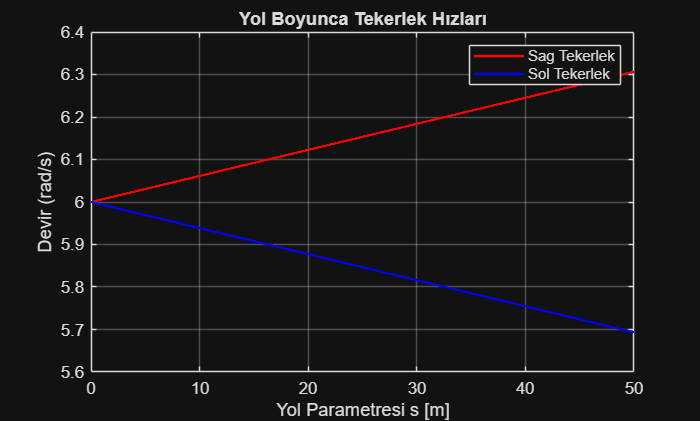


%% Tekerlek Hızları Grafiği
figure;
plot(s_param, w_sag_teker,'r','LineWidth',1.5); hold on;
plot(s_param, w_sol_teker,'b','LineWidth',1.5);
grid on;
xlabel('Yol Parametresi s [m]');
ylabel('Devir (rad/s)');
legend('Sag Tekerlek','Sol Tekerlek');
title('Yol Boyunca Tekerlek Hızları');

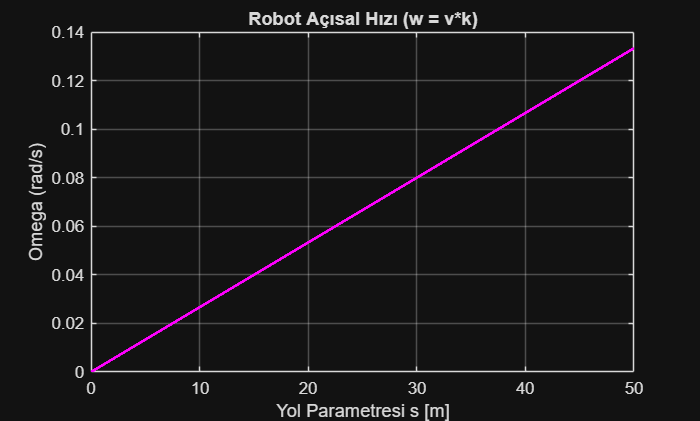


%% Açısal Hız Grafiği
figure;
plot(s_param, w_robot,'m','LineWidth',1.8);
grid on;
xlabel('Yol Parametresi s [m]');
ylabel('Omega (rad/s)');
title('Robot Açısal Hızı (w = v*k)');

BÖLÜM D: DUBINS & REEDS-SHEPP (MATLAB Navigation Toolbox tercih)

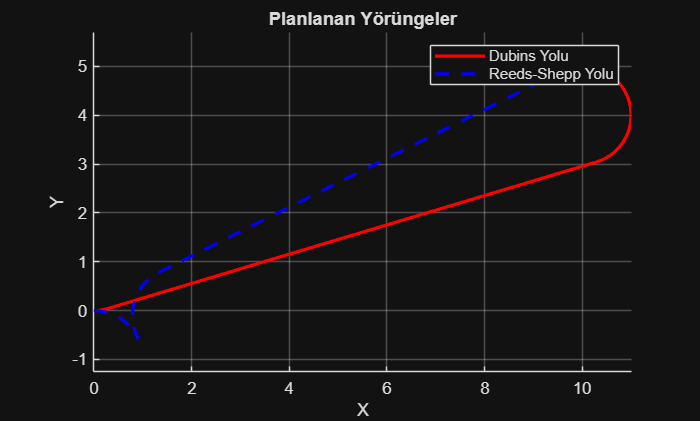

close all;

%% Başlangıç ve Hedef Konumları
baslangic = [0 0 0];
hedef = [10 5 pi];

%% Bağlantı Tanımları
baglanti_Dubins = dubinsConnection('MinTurningRadius', 1.0);
baglanti_RS     = reedsSheppConnection('MinTurningRadius', 1.0);

%% Yol Hesaplamaları
[yol_Dubins, ~] = connect(baglanti_Dubins, baslangic, hedef);
[yol_RS, ~]     = connect(baglanti_RS,     baslangic, hedef);

%% Yolları sık aralıklarla örnekle
adim_mesafe = 0.01;

durumlar_D = interpolate(yol_Dubins{1}, 0:adim_mesafe:yol_Dubins{1}.Length);
durumlar_R = interpolate(yol_RS{1},     0:adim_mesafe:yol_RS{1}.Length);

%% Çizdir
figure; hold on; grid on; axis equal;
plot(durumlar_D(:,1), durumlar_D(:,2), 'r', 'LineWidth', 2);
plot(durumlar_R(:,1), durumlar_R(:,2), 'b--', 'LineWidth', 2);

legend("Dubins Yolu","Reeds-Shepp Yolu");
title("Planlanan Yörüngeler");
xlabel("X");
ylabel("Y");

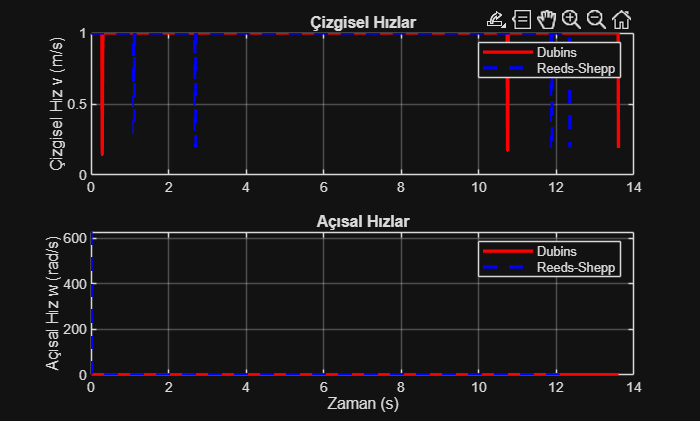


%% Konum ve başlık verilerini ayır
% DUBINS
x_D = durumlar_D(:,1);
y_D = durumlar_D(:,2);
th_D = durumlar_D(:,3);

% REEDS-SHEPP
x_R = durumlar_R(:,1);
y_R = durumlar_R(:,2);
th_R = durumlar_R(:,3);

%% Zaman vektörleri (sabit adım)
t_D = (0:length(x_D)-2)*adim_mesafe;
t_R = (0:length(x_R)-2)*adim_mesafe;

%% Hız Hesaplamaları
% Çizgisel Hız
v_lin_D = sqrt(diff(x_D).^2 + diff(y_D).^2) ./ adim_mesafe;
v_lin_R = sqrt(diff(x_R).^2 + diff(y_R).^2) ./ adim_mesafe;

% Açısal Hız
w_acisal_D = diff(th_D) ./ adim_mesafe;
w_acisal_R = diff(th_R) ./ adim_mesafe;

%% Grafikler
figure;
subplot(2,1,1);
plot(t_D, v_lin_D, 'r', 'LineWidth', 2); hold on;
plot(t_R, v_lin_R, 'b--', 'LineWidth', 2);
grid on;
ylabel("Çizgisel Hız v (m/s)");
title("Çizgisel Hızlar");
legend("Dubins","Reeds-Shepp");

subplot(2,1,2);
plot(t_D, w_acisal_D, 'r', 'LineWidth', 2); hold on;
plot(t_R, w_acisal_R, 'b--', 'LineWidth', 2);
grid on;
ylabel("Açısal Hız w (rad/s)");
xlabel("Zaman (s)");
title("Açısal Hızlar");
legend("Dubins","Reeds-Shepp");

LOCAL FONKSİYONLAR

function profil_cikis = rampa_olustur(t_vektoru, t_bas, t_bit, hiz_maks, t_rampa)
    % t_vektoru ile aynı uzunlukta vektör döndürür; t_bas..t_bit arası trapez
    profil_cikis = zeros(size(t_vektoru));
    indeksler = (t_vektoru>=t_bas) & (t_vektoru<=t_bit);
    aktif_indeks = find(indeksler);
    if isempty(aktif_indeks)
        return;
    end
    sure = t_bit - t_bas;
    rampa = min(t_rampa, sure/2);
    n_sayisi = length(aktif_indeks);
    t_yerel = linspace(0,sure,n_sayisi);
    profil = zeros(1,n_sayisi);
    if rampa == 0
        profil(:) = hiz_maks;
    else
        for k=1:n_sayisi
            ti = t_yerel(k);
            if ti < rampa
                profil(k) = (hiz_maks/rampa)*ti;
            elseif ti <= sure - rampa
                profil(k) = hiz_maks;
            else
                profil(k) = hiz_maks * (1 - (ti-(sure-rampa))/rampa);
            end
        end
    end
    profil_cikis(aktif_indeks) = profil;
end